# Fingerprinting the audio signal

This script takes a audio as the input then it converts the audio signal into spectrogram, which is actually the audio time versus frequency representation of the signal, from the spectrogram peak frequencies are kept to make a digital fingerprint for the audio

## Loading the audio file

Loading the specific audio file, resampling the song, and pre-processing the file for the spectrogram

clc, clearvars, close all;

[song,fs] = audioread("data/oh_lord.mp3");
song = single(song);
% converting the song to mono audio if the song is stereo
if size(song,2) == 2
    song = mean(song,2);
end
target_fs = 8400; % frequency in hz

if fs ~= target_fs
    song = resample(song, target_fs, fs);
    fs = target_fs; 
end

## Making the spectrogram of the Audio

Selecting the suitable parameters for the spectrogram, and perforoming the spectrogram operation

n_overlap = 512;
n_fft = 1024;
window = hanning(n_fft); % Window length is based on n_fft

[s,f,t] = spectrogram(song,window,n_overlap,n_fft,fs,"yaxis");
mag_s = abs(s);

figure(1);
imagesc(t,f,20*log10(mag_s));
axis xy;
colormap('gray'); colorbar;
xlabel("Time(s)"); ylabel("Frequency");

## Finding the peaks

First from the "mag_s" the regional peaks are determined, 

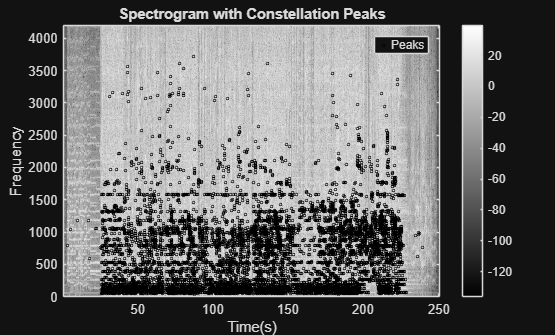

isPeak = imregionalmax(mag_s);

peakThresholdPercent = 98;
threshold = prctile(mag_s(:), peakThresholdPercent);
finalPeakMask = isPeak & (mag_s > threshold);

[freq_idx, time_idx] = find(finalPeakMask);

hold on;
peakTimes = t(time_idx);
peakFreqs = f(freq_idx);
plot(peakTimes, peakFreqs, 'ko', 'MarkerSize', 2);
title('Spectrogram with Constellation Peaks');
legend('Peaks');
%xlim([50 55]);
%ylim([300 500]);
hold off; 

disp(['Found ' num2str(length(peakTimes)) ' peaks.']);

Found 8914 peaks.


peaks = sum(sum(isPeak))

peaks = 149604

peakIndices = [time_idx, freq_idx];


## Making the hashmap based on the peaks

% This section creates the "fingerprint" by pairing peaks together.
% Each pair consists of an "anchor" peak and a "target" peak
% from its "target zone".

% 1. Define the "Target Zone" parameters
% These parameters define the search window for target peaks, relative
% to each anchor peak.
targetTimeStart = 3;  % Start 3 time steps after anchor (e.g., ~0.07s)
targetTimeEnd = 80;   % End 80 time steps after anchor (e.g., ~1.8s)
targetFreqRange = 50; % +/- 50 frequency bins

% 2. Initialize the Hash Map
% We use a containers.Map for the hashmap. It's MATLAB's version
% of a dictionary or hash table.
% Key: A string hash "freq1:freq2:deltaTime"
% Value: A list of anchor times (in seconds) where that hash occurred.
hashmap = containers.Map('KeyType', 'char', 'ValueType', 'any');

% 3. Sort peaks by time index
% This is crucial for efficiently finding pairs.
peakIndices = sortrows(peakIndices, 1); % Sort by time_idx (column 1)
numPeaks = size(peakIndices, 1);

disp('Generating hashes from peaks...');

Generating hashes from peaks...



% 4. Iterate over each peak, treating it as the "anchor"
for i = 1:numPeaks
    anchorPeak = peakIndices(i, :);
    anchorTimeIdx = anchorPeak(1);
    anchorFreqIdx = anchorPeak(2);
    
    % Define the target zone boundaries for this anchor
    timeStart = anchorTimeIdx + targetTimeStart;
    timeEnd = anchorTimeIdx + targetTimeEnd;
    freqLow = anchorFreqIdx - targetFreqRange;
    freqHigh = anchorFreqIdx + targetFreqRange;
    
    % Find all peaks that fall within this target zone.
    % We search in the *remaining* peaks list for efficiency, but for
    % simplicity here, we'll search the whole list. A more optimized
    % approach would be to only search from index i+1.
    
    % This is a vectorized logical search:
    isTarget = (peakIndices(:, 1) >= timeStart) & ...
               (peakIndices(:, 1) <= timeEnd) & ...
               (peakIndices(:, 2) >= freqLow) & ...
               (peakIndices(:, 2) <= freqHigh);
               
    % Get the indices of the target peaks
    targetPeakIndices = find(isTarget);
    
    % 5. Create a hash for each (anchor, target) pair
    for j = 1:length(targetPeakIndices)
        targetPeak = peakIndices(targetPeakIndices(j), :);
        targetTimeIdx = targetPeak(1);
        targetFreqIdx = targetPeak(2);
        
        % Calculate the time difference (in time *indices*, not seconds)
        deltaTime = targetTimeIdx - anchorTimeIdx;
        
        % Create the unique hash string: "freq1:freq2:deltaTime"
        hashString = sprintf('%d:%d:%d', anchorFreqIdx, targetFreqIdx, deltaTime);
        
        % Store the hash in the map
        % We store the *actual time in seconds* of the anchor
        anchorTime = t(anchorTimeIdx);
        
        if isKey(hashmap, hashString)
            % If this hash already exists, append this anchor's time
            hashmap(hashString) = [hashmap(hashString), anchorTime];
        else
            % Otherwise, create a new entry (a new list) for this hash
            hashmap(hashString) = [anchorTime];
        end
    end
end

disp(['Finished generating hashes. Found ' num2str(hashmap.Count) ' unique hashes.']);

Finished generating hashes. Found 379708 unique hashes.



% 'hashmap' is now your complete audio fingerprint, ready to be saved
% or used for matching.